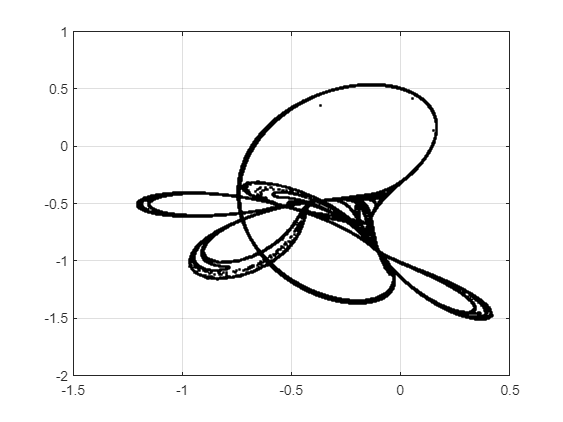


n = 100000;

x = zeros(1,n);
y = zeros(1,n);

x(1) = 0.15032020;
y(1) = 0.14022023;
xprev = x(1);
yprev = y(1);

for i = 2:n
x(i) = xprev^2 - yprev^2 + 0.9*xprev -0.6*yprev;
y(i) = 2*xprev*yprev + 2*xprev + 0.5*yprev;
xprev = x(i);
yprev = y(i);
end



for i=1:n
    plot(x(i),y(i),'k.')
    hold on
    grid on
end